This equation is known as the *van der Pol* oscillator. In it, the "damping" term changes sign depending on the instantaneous size of the solution. This way, large values are damped down, but small values are amped up.


$$u'' + u - \mu(1-u^2)u' = 0,\qquad u(0)=2,\quad u'(0)=0$$


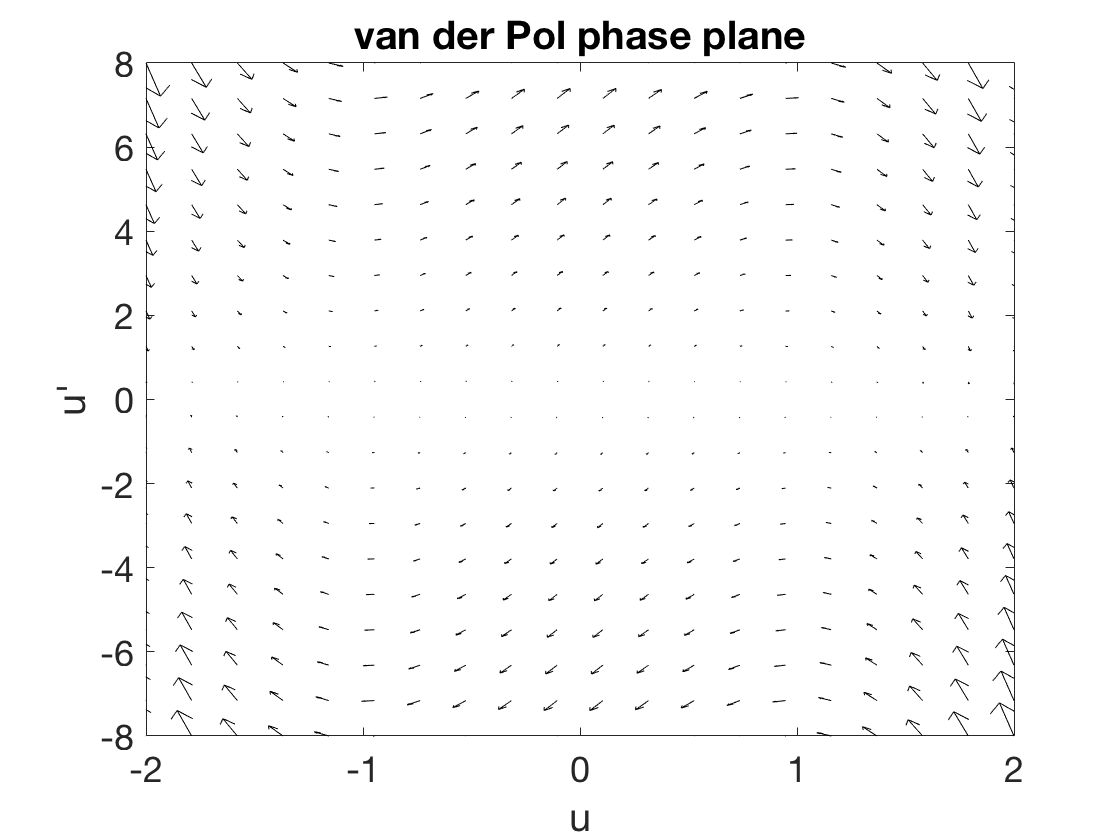

V = chebop([0 60]);
V.op = @(u) diff(u,2) + u - 4*(1-u^2)*diff(u);
clf, quiver(V,[-2 2 -8 8],'k')
xlabel("u"), ylabel("u'")
title('van der Pol phase plane')

Pretty much anywhere we start the system, it ends up settling into a particular loop in phase space. (Perhaps you can find initial conditions for which this does not happen....)

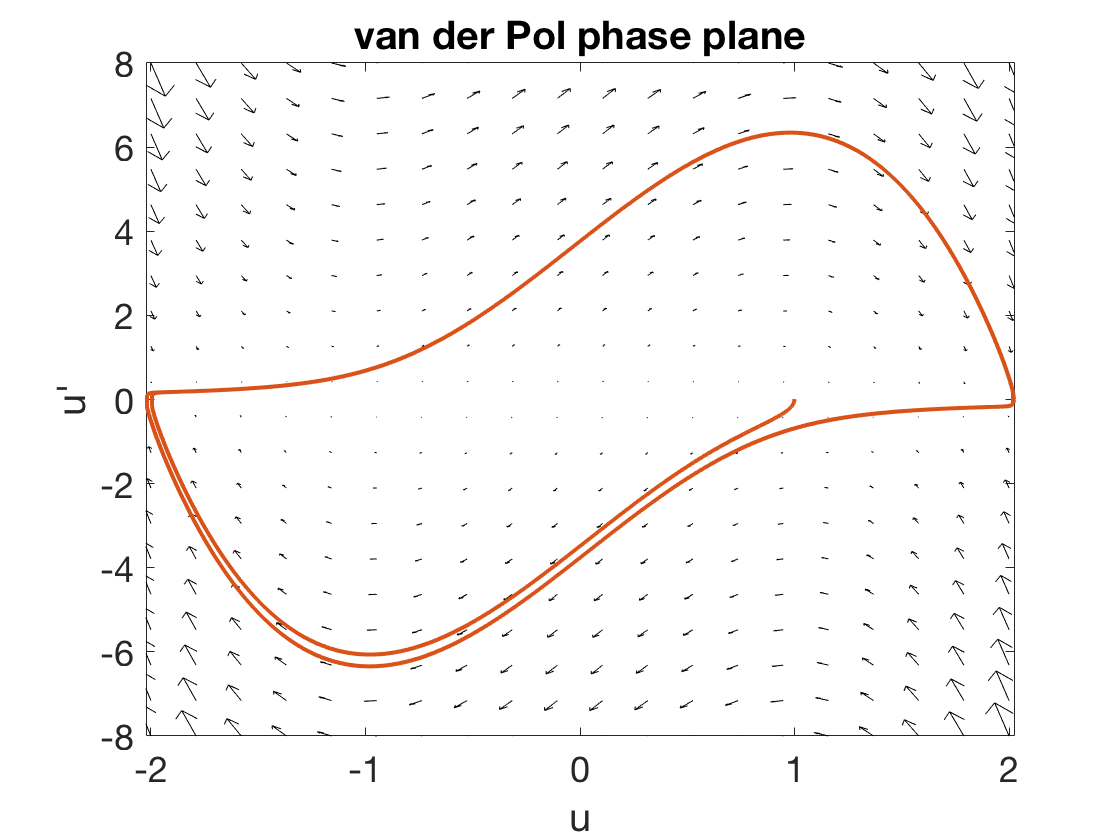

V.lbc = [1 0.01];
u = V\0;
hold on, plot(u,diff(u))

## Limit cycle

The apparent loop is called a *limit cycle*. This cycle itself is a periodic solution, but in general solutions only approach it without quite getting there. If we look at every other time the solution goes through the line $u=0$, we see that the result is nearly periodic.

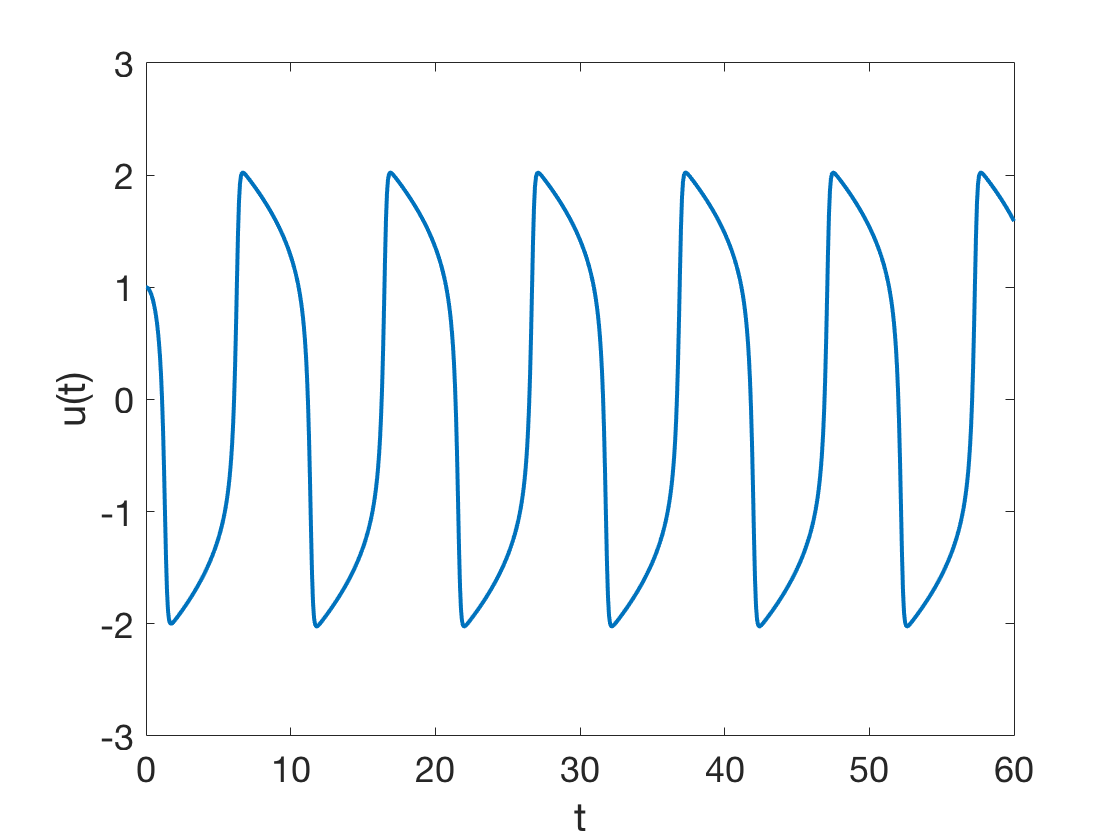

t0 =     1.1104
    6.0890
   11.1908
   16.2925
   21.3943
   26.4961
   31.5978
   36.6996
   41.8013
   46.9031


t0 = find(u==0)

format long
delta_t = diff(t0(1:2:end))

delta_t =   10.080350963250591
  10.203523691017876
  10.203523691110437
  10.203523691040189
  10.203523691077436


We can pull out just one of the (near) cycles. 

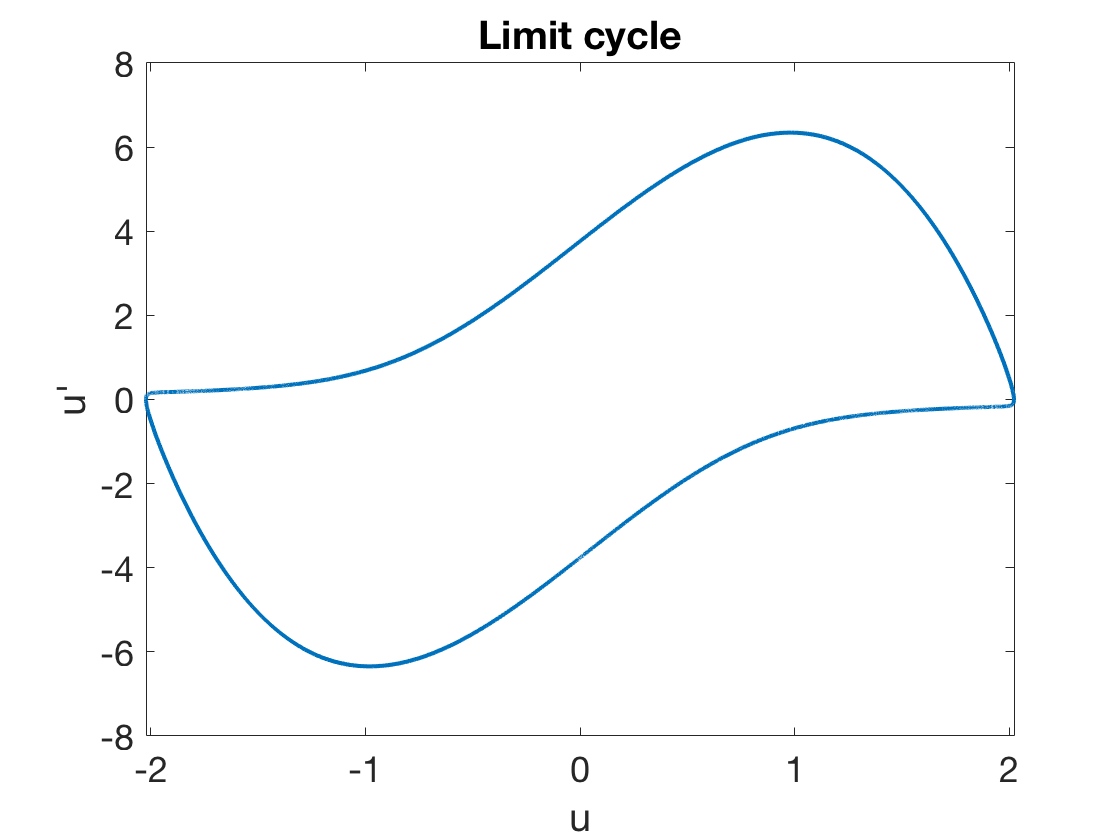

ucycle = u{t0(5),t0(7)};
clf, plot(ucycle,diff(ucycle))
xlabel("u"), ylabel("u'")
title('Limit cycle')

If we want to get the limit cycle exactly, though, we need to be a little tricky. This is like a boundary-value problem with an extra condition and corresponding extra unknown, the period $T$.


$$\frac{d^2u}{dt^2} + u - \mu(1-u^2) \frac{du}{dt} = 0,\qquad u(0)=u(T)=0,\quad u'(0)=u'(T)
$$


Fortunately, we can transform it to a problem on a known domain by a simple change of variable. 


$$s = \frac{t}{T} \in [0,1]\\
\frac{1}{T^2} \frac{d^2u}{ds^2} + u - \mu(1-u^2)\frac{1}{T} \frac{du}{ds} = 0,\qquad u(0)=u(1)=0,\quad u'(0)=u'(1)$$


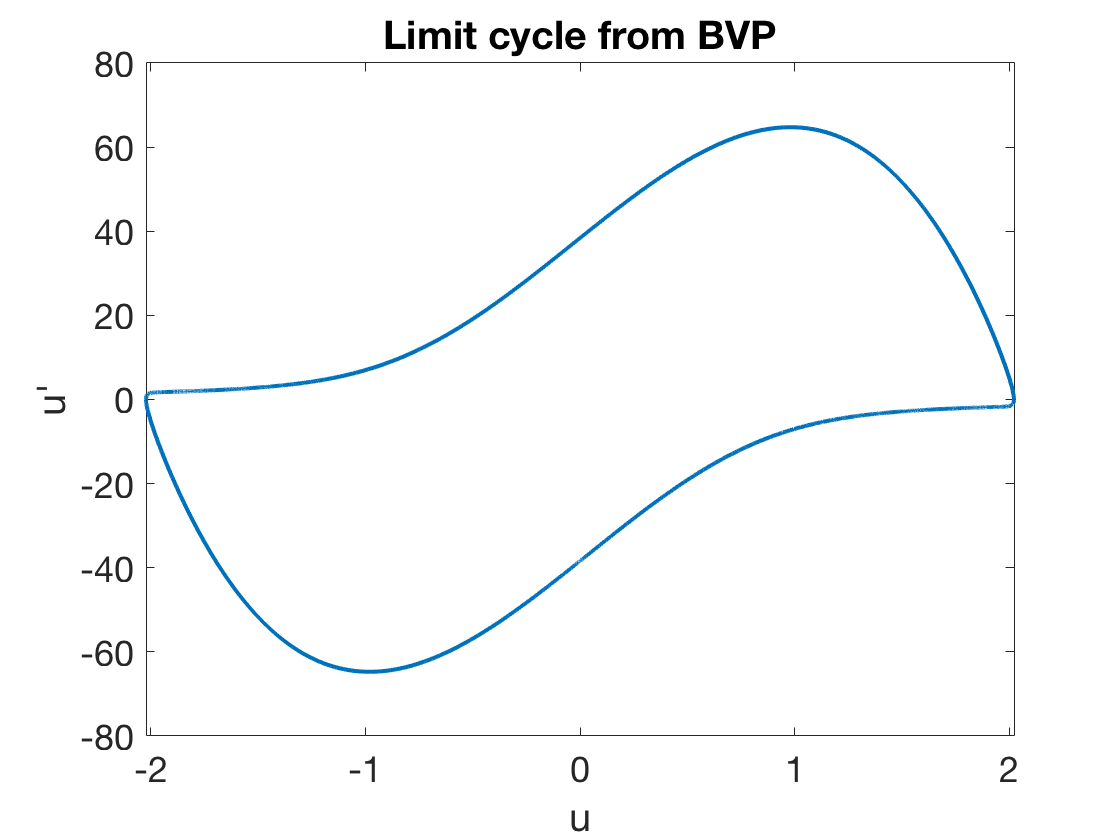

V = chebop([0 1]);
V.op = @(s,u,T) diff(u,2)/T^2 + u - 4*(1-u^2)*diff(u)/T;
V.bc = @(s,u,T) [  u(0);
                   u(1);
                   deriv(u,0)-deriv(u,1);
                    ];
V.init = [newDomain(ucycle,[0 1]); 10 ];
[u,T] = V\0;
plot(u,diff(u))
xlabel("u"), ylabel("u'")
title('Limit cycle from BVP')

Here's what we found the period to be.

T

T =   10.203523690993659